# Differential correction for Lyapunov orbits


global FORWARD tol mu a Lpt
FORWARD = 1;
tol = 1e-10;
a=1;
Lpt = 0;
mu = 9.537e-4; % Sun-Jupiter

poly1 = [1  -1*(3-mu)  (3-2*mu)  -mu   2*mu  -mu ];

rt1 = roots(poly1);
for k=1:5
    if isreal(rt1(k)) 
        gamma = rt1(k)
    end
end

gamma = 0.0667


xLpt = (1-mu)-gamma

xLpt = 0.9324


T = 2*pi ; % period of primaries in non-dimensional units

% L1 eigenbasis

mubar=mu/abs(xLpt-1+mu)^3 + (1-mu)/abs(xLpt+mu)^3;

aa=1+2*mubar;
b =mubar -1 ;

lam = sqrt( 0.5*(mubar-2+sqrt(9*mubar^2-8*mubar)));
nu  = sqrt(-0.5*(mubar-2-sqrt(9*mubar^2-8*mubar)));

sigma =  2*lam/(lam^2 + b)

sigma = 0.5042

tau   =-(nu^2  + aa)/(2*nu)

tau = -3.3601


u1 = [ 1 ; -sigma ;  lam ; -lam*sigma ] ;
u2 = [ 1 ;  sigma ; -lam ; -lam*sigma ] ;
u  = [ 1 ;    0   ;   0  ;   nu*tau   ] ;
v  = [ 0 ;   tau  ;  -nu ;     0      ] ;


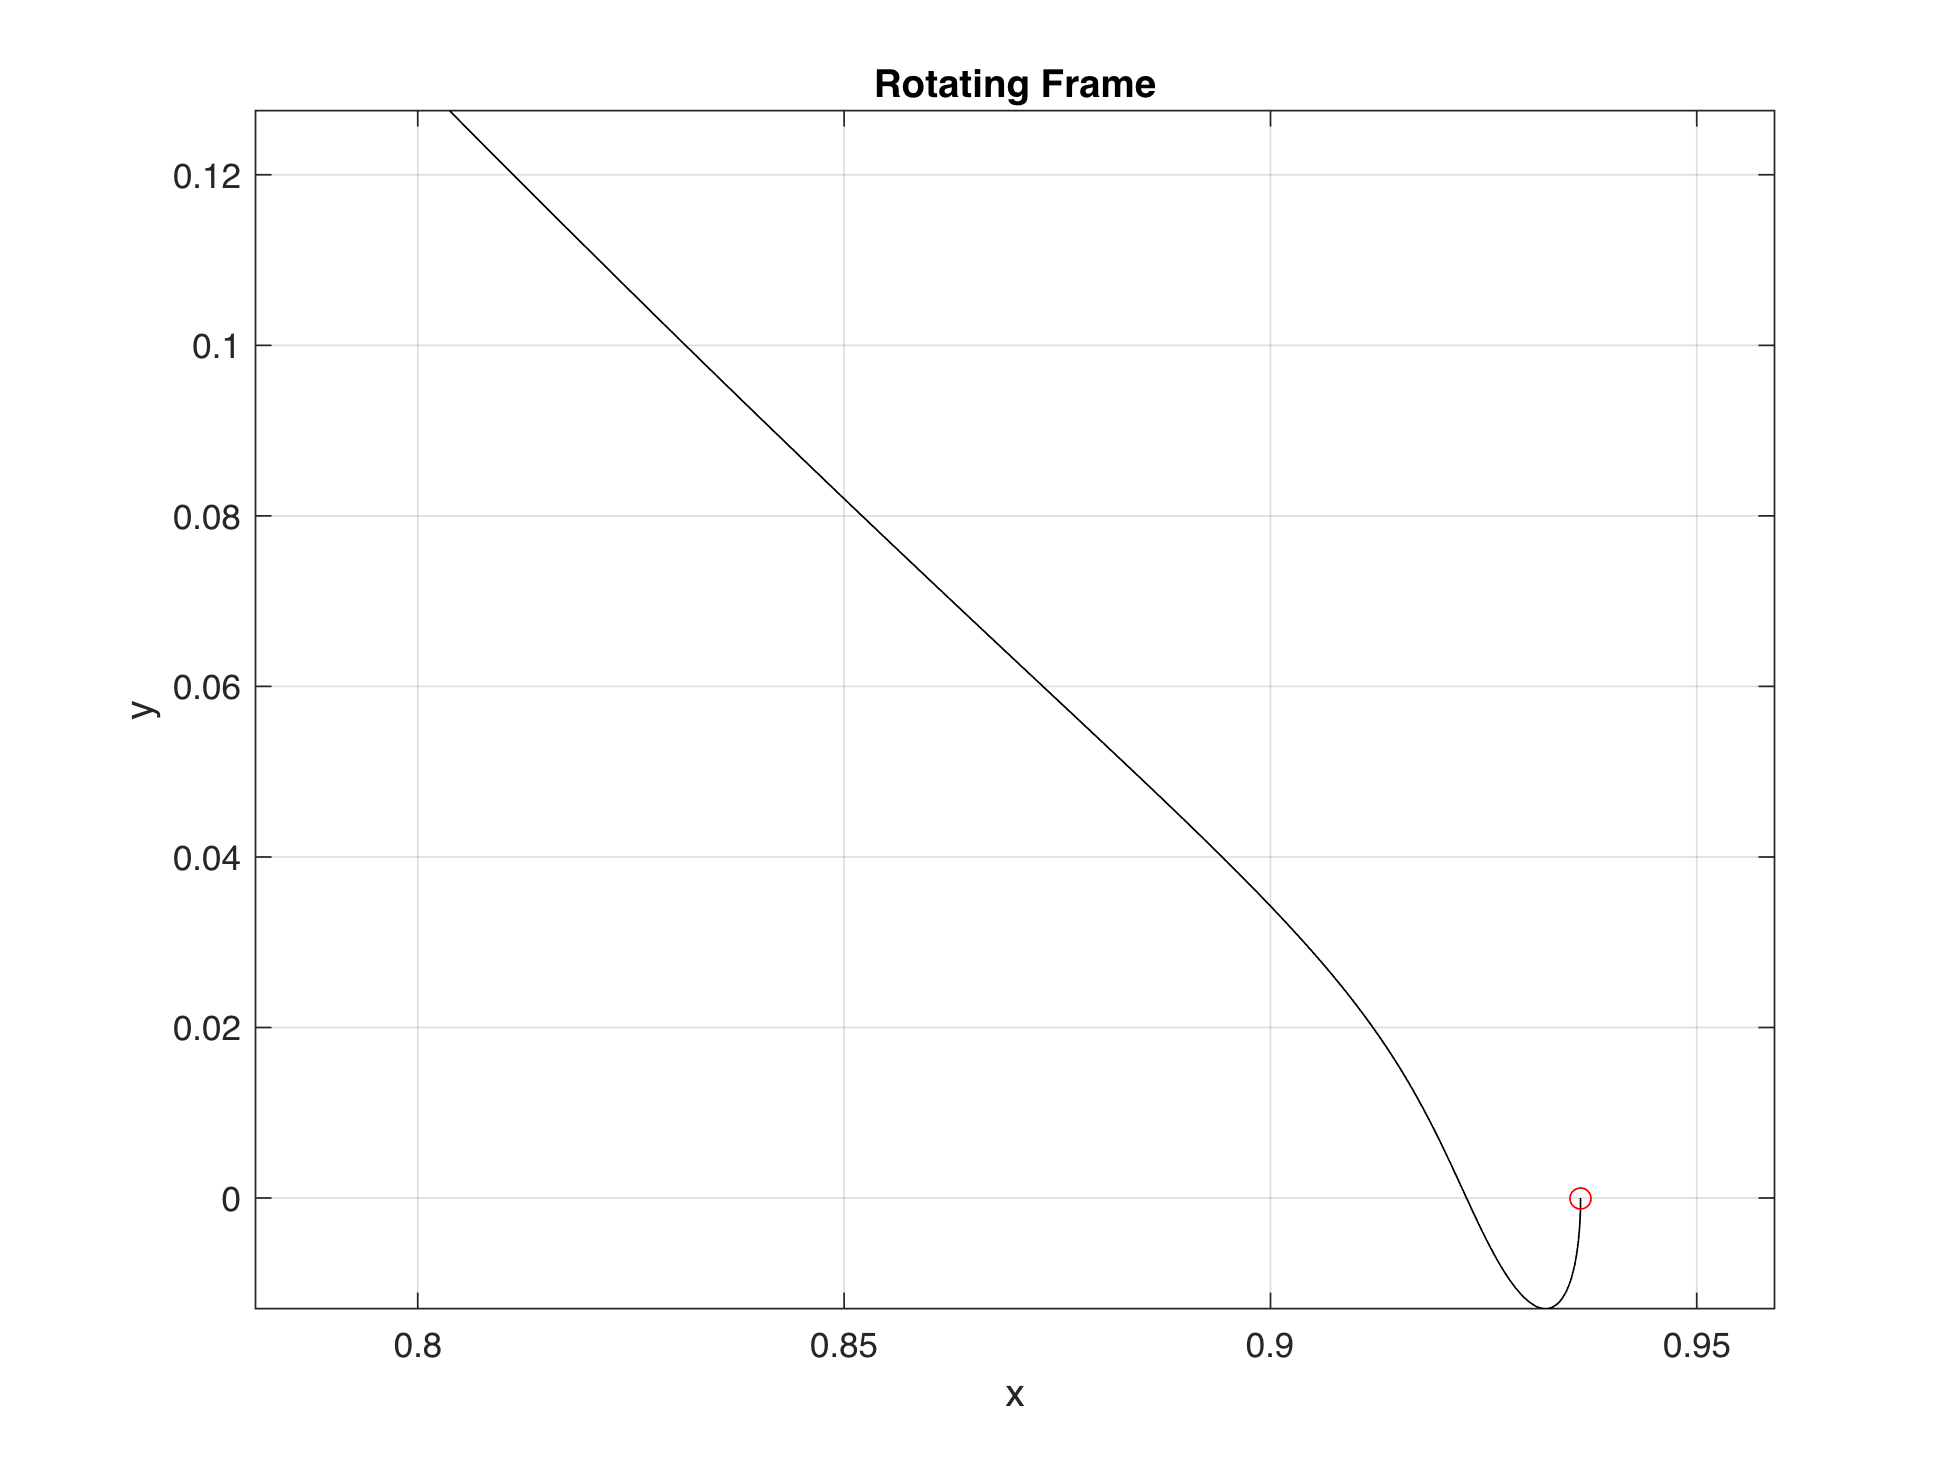

% Compute small periodic orbit (planar Lyapunov orbit)

tfinal = 2*pi/nu;

tspan = 0:0.001*T:tfinal;

XL = [ xLpt ; 0 ; 0 ; 0 ] ;

displacement = 4e-3; % nondimensional displacement from L
X0 = XL + displacement*u ; % initial condition

opts = odeset('AbsTol',1e-8,'RelTol',1e-6);
[t,X] = ode45(@(t,X) prtbp(t,X), tspan, X0, opts) ;

x =X(:,1); 
y =X(:,2);

plot(x,y,'k',X0(1),X0(2),'ro');
title('Rotating Frame'); 
xlabel('x'); ylabel('y');
axis equal; grid on

x0g = X0;
%[t1,xx1]=find0(x0g);
[x0po,t1] = liadifcor(x0g);

attempt = 1

attempt = 2

attempt = 3

attempt = 4

attempt = 5

attempt = 6

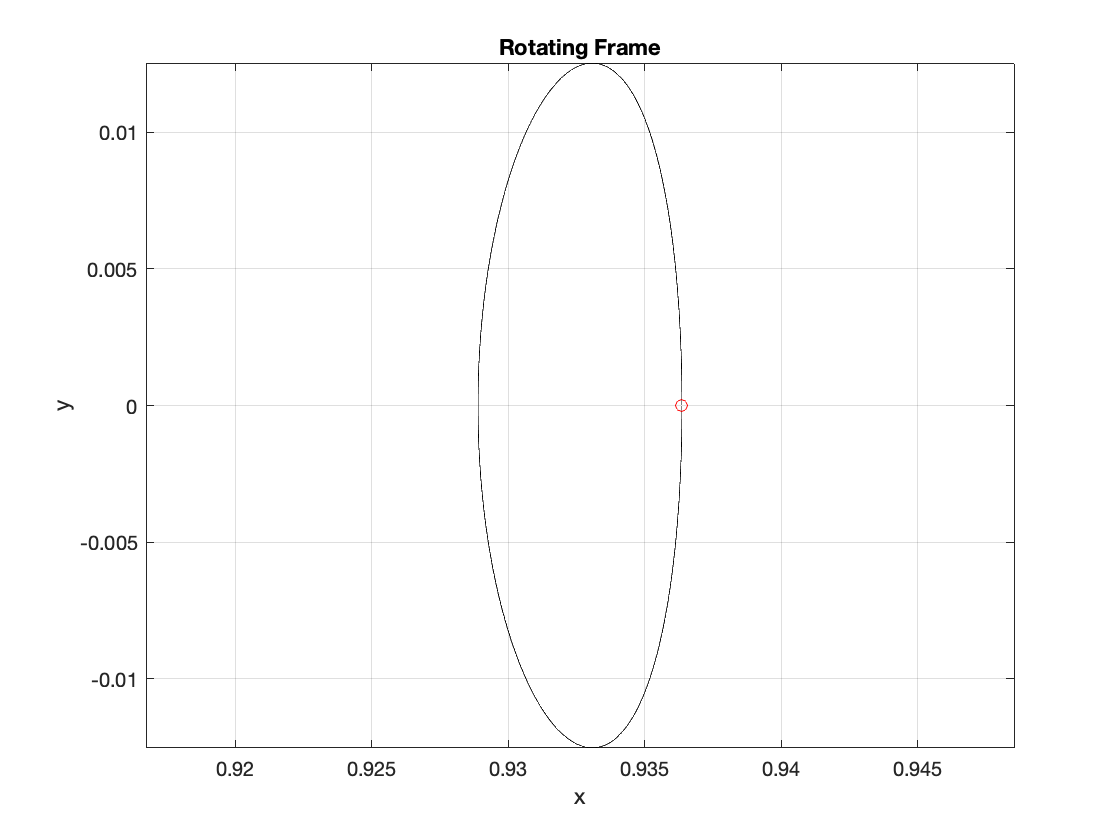

Tpo = 2*t1 ;

tspan = 0:0.001*Tpo:Tpo;

opts = odeset('AbsTol',1e-8,'RelTol',1e-6);
[t,X] = ode45(@(t,X) prtbp(t,X), tspan, x0po, opts) ;

x =X(:,1); 
y =X(:,2);

plot(x,y,'k',X0(1),X0(2),'ro');
title('Rotating Frame'); 
xlabel('x'); ylabel('y');
axis equal; grid on

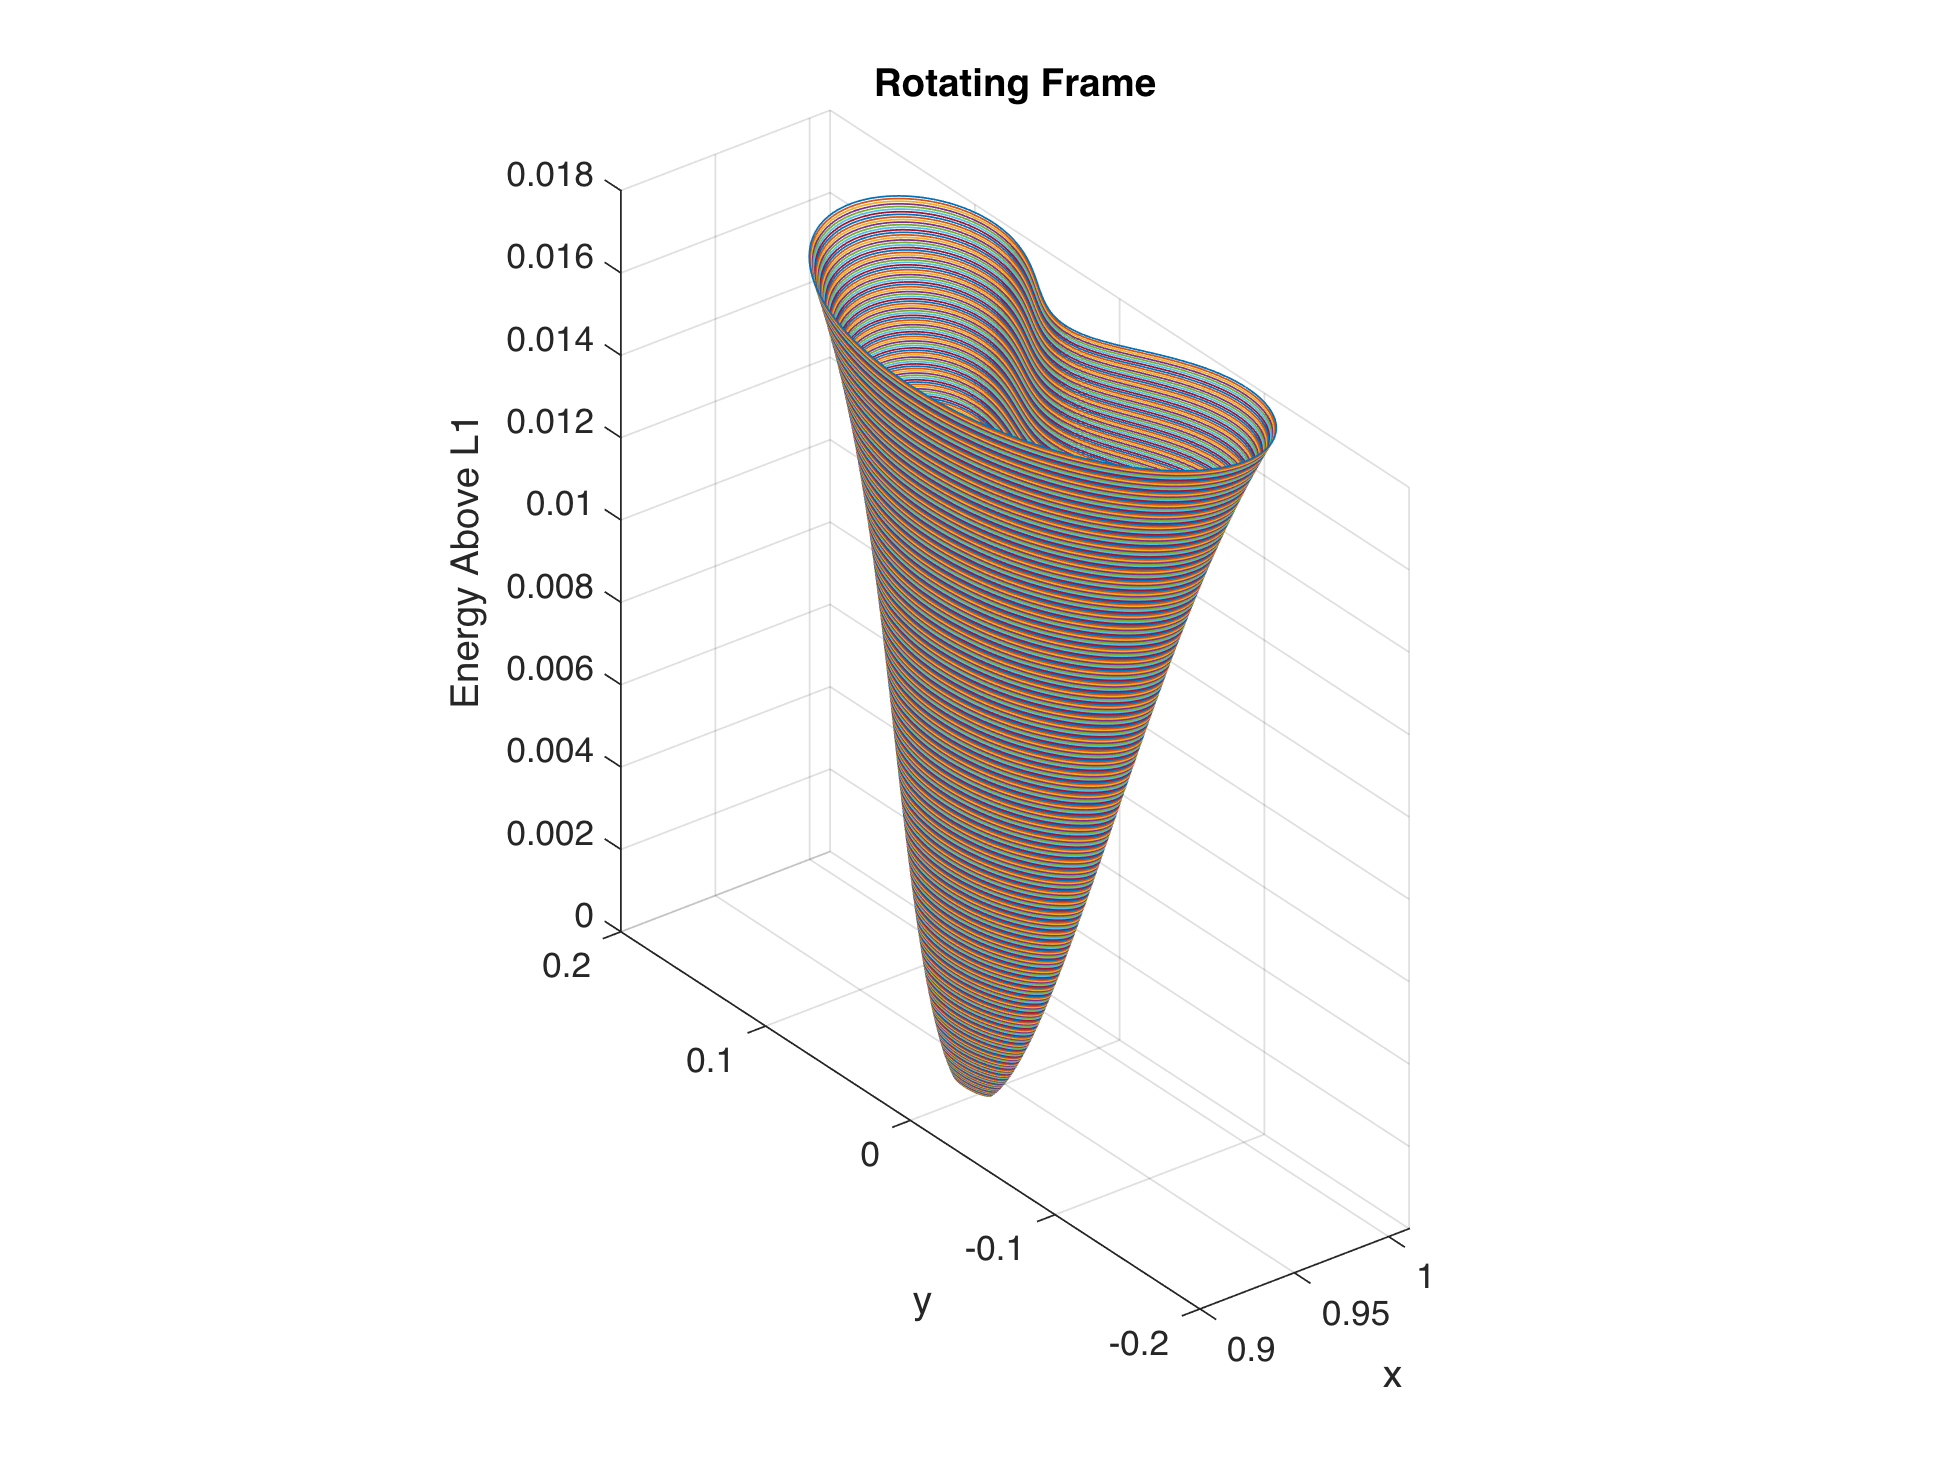

%% Lyapunov Family Generation
%% Differential Correction and Numerical Continuation
%% Only need to run once (takes a while)
% Lpt = 1;
% xmin = X0(1)-xLpt;
% xmax = 0.05 ;
% dx   = 0.0001 ;
% x0i = x0po ;
% 
% [xL,t1L] = liafam(mu,Lpt,xmin,xmax,dx,x0i)

Epo = [];

E1 = energy(XL',mu);

for k=length(xL):-1:1
    x0=xL(k,:); t1=t1L(k);
    Epo(k) = energy(x0,mu);
    [x,t]=int(x0,t1);
    xx=[x(:,1) x(:,2) ; flipud(x(:,1)) -flipud(x(:,2))];
    plot3(xx(:,1),xx(:,2),(Epo(k)-E1)*ones(size(xx(:,1))));
    if k==length(xL), hold on; grid on; end
end

title('Rotating Frame'); 
xlabel('x'); 
ylabel('y'); 
zlabel('Energy Above L1');
% Code to make axis equal only in x and y directions
h = get(gca,'DataAspectRatio');
if h(3)==1
      set(gca,'DataAspectRatio',[1 1 1/max(h(1:2))]);
else
      set(gca,'DataAspectRatio',[1 1 h(3)]);
end

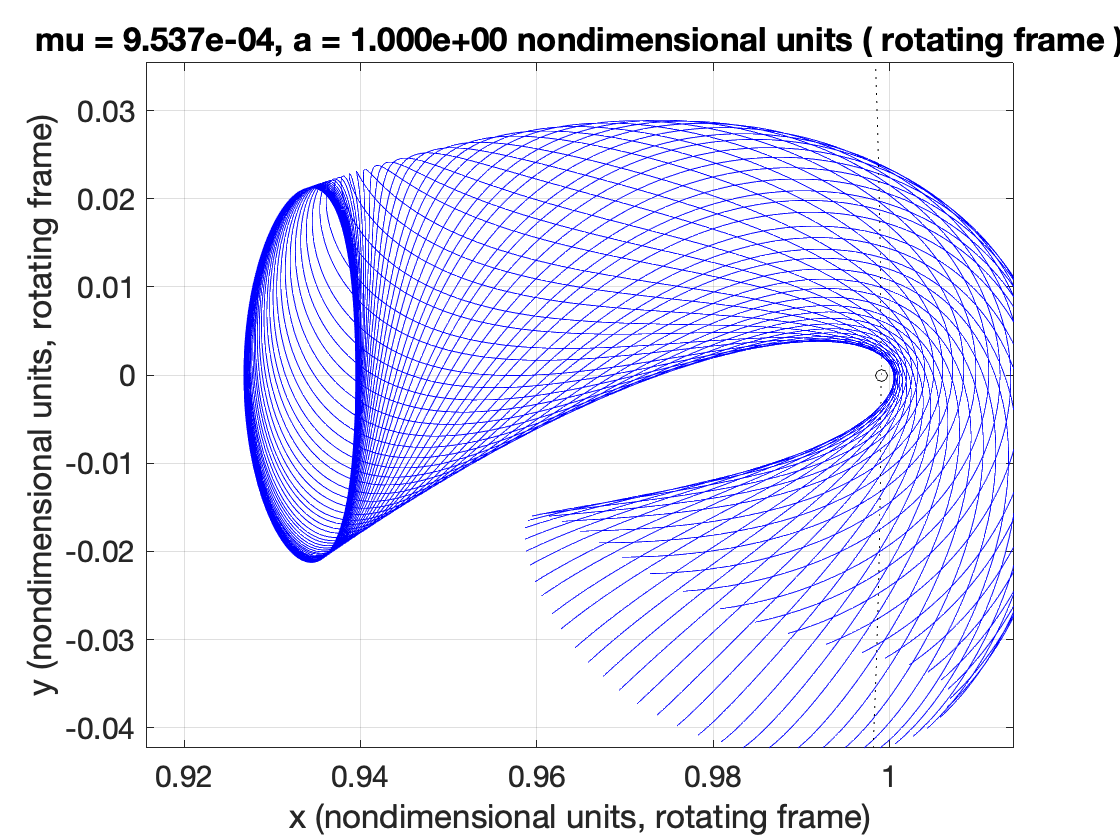

k_en=32; % Corresponds to energy seen in book section 4.5

x0=xL(k_en,:);T=2*t1L(k_en);
x0=[x0(1) x0(2) 0 x0(3) x0(4) 0];
[x,t]=int(x0,T); 
Lpt=0;
figure
plotX(x,'k');
axis([0.9157    1.0141   -0.0423    0.0354])

stbl=1;    % stable manifold
dir=+1;	   % positive branch
k=0; ysos=[]; ydsos=[];
for frac = 0:0.02:0.98 % some number between zero and one to parameterize manifold
    x0W = orbitman(x0,T,frac,stbl,dir); 
    tf=.7*(2*pi);
    [xW,tW]=int(x0W,tf);
    plotX(xW,'b',1);
    [Xy0,Ty0]=sosx0(xW,tW,2);
    k=k+1;
    ysos (k) = Xy0(2);
    ydsos(k) = Xy0(5);
end
axis([0.9157    1.0141   -0.0423    0.0354])
set(gca,'fontsize',15)

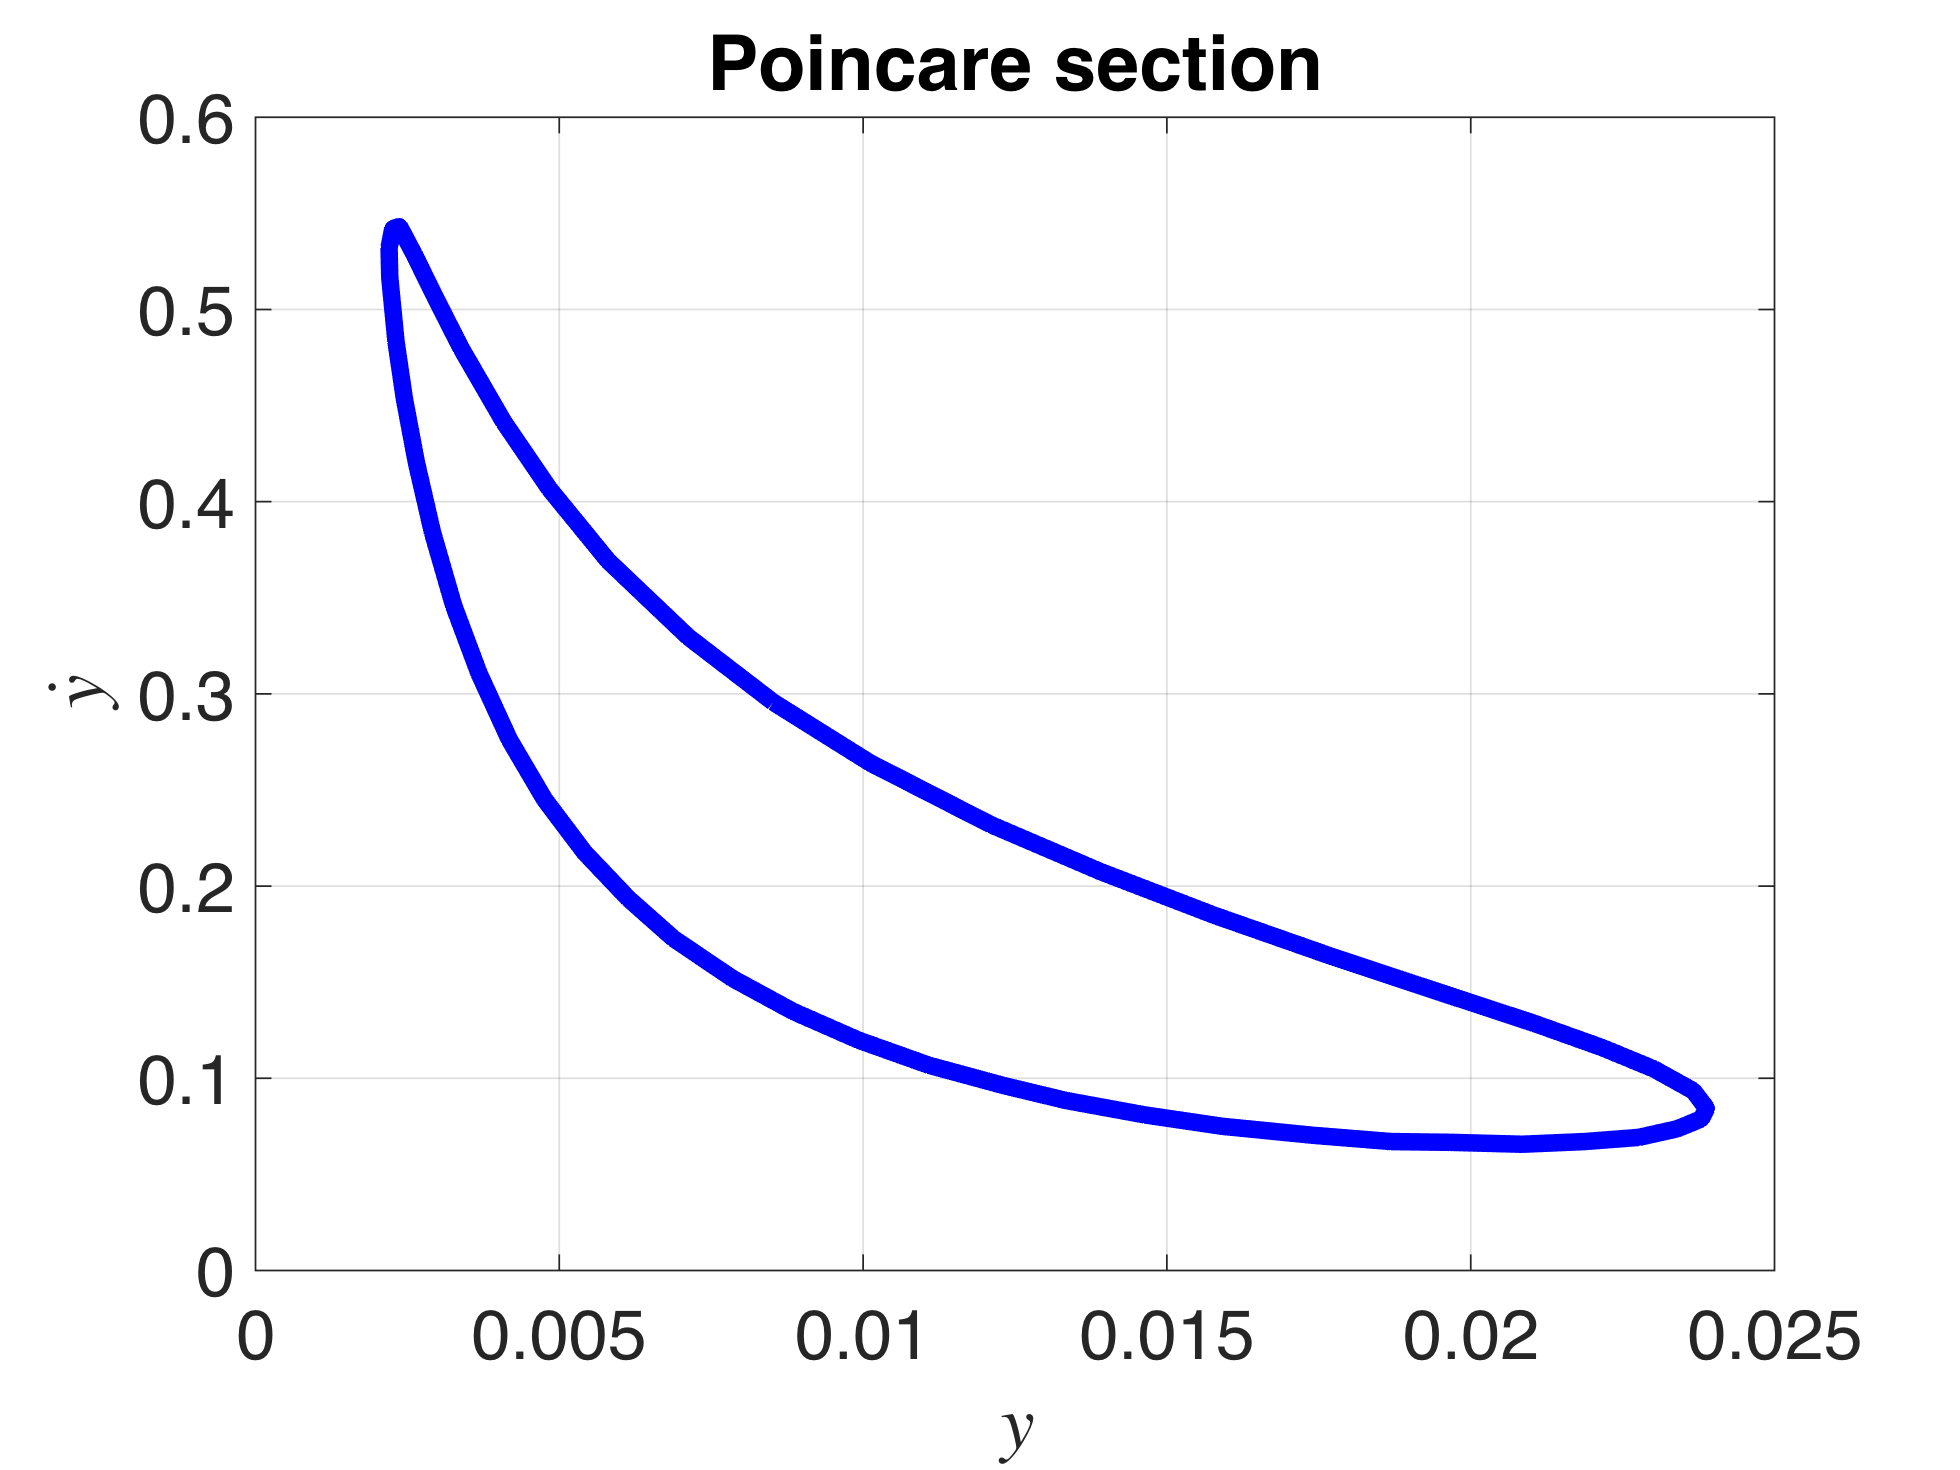

ysos (end+1)=ysos (1);
ydsos(end+1)=ydsos(1);

figure
plot(ysos,ydsos,'b-','LineWidth',5); 
title('Poincare section');
xlabel('$y$','Interpreter','latex')
ylabel('$\dot y$','Interpreter','latex')
set(gca,'fontsize',20); grid on;

function xdot = prtbp(t,x)
% xdot = prtbp(t,x)
%
% with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
%
% -L3----m1--+-------L1--m2--L2-
%
%                L5
%
% Shane Ross (revised 9.23.97)
global mu

mu1=1-mu; % mass of larger  primary (nearest origin on left)
mu2=  mu; % mass of smaller primary (furthest from origin on right)

r3= ((x(1)+mu2)^2 + x(2)^2)^1.5;     % r: distance to m1, LARGER MASS
R3= ((x(1)-mu1)^2 + x(2)^2)^1.5;     % R: distance to m2, smaller mass

xdot    = zeros(4,1);
xdot(1) = x(3);
xdot(2) = x(4);
xdot(3) = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3)+2*x(4);
xdot(4) = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3)-2*x(3);
end


%% Compute 3-Body Energy

function E = energy(X,mu)

mu1=1-mu;mu2=mu;

Vsqrd= X(:,3).^2+X(:,4).^2 ;
Ubar = - mu1./sqrt((X(:,1)+mu2).^2+X(:,2).^2) ...
       - mu2./sqrt((X(:,1)-mu1).^2+X(:,2).^2) ...
       - 0.5*(X(:,1).^2+X(:,2).^2) - 0.5*mu1*mu2 ;

E = 0.5*Vsqrd + Ubar ;

end


function Xin = rot2iner(X,t,M,mu,del)
% Xin=rot2iner(X,T,M,mu,del);
%
% Transformation from M body-centered rotating (nondim.) coordinates to
% inertial (nondim.) coordinates
%
% M = 2 : smaller mass(M2) centered inertial coordinates
% M = 1 : LARGER  mass(M1) centered inertial coordinates
% M = 0 : center-of-mass   centered inertial coordinates
%
% X   = state 4- or 6-vector matrix (in nondim. rotating coordinates)
% t   = nondimensional CR3BP time
% del = the rotation offset at time t=0 (in radians)
%
% Xrot = inv(B)*(Xin - A)
% see p.6 of Cassall(1996)
%
% NOTE: nondim. means nondimensional CR3BP units where 
%	sum of primaries' mass = 1
%	constant distance between primaries = 1
%	period of primaries' orbit = 2*pi
% 
%-----------------------------------------------------------------------
% CR3BP (Circular Restricted Three-Body [Gravitational] Problem)
% with the LARGER MASS, M1 to the left of the origin at (-mu,0)
% and the smaller mass, M2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%       (rotating coords)
%
%                 L4
% -L3------M1--+-----L1--M2--L2-
%                 L5
%
% Shane Ross (revised 7.15.97)
%

% Defaults
if nargin<=4
    del=0;
    if nargin<=3
        mu=0;
        if nargin<=2
            M=0;
        end
    end
end

if     M==1, d= -mu; 	% distance to LARGER  primary in CR3BP (M1)
elseif M==2, d=1-mu;	% distance to smaller primary in CR3BP (M2)
elseif M==0, d=0;	    % center-of-mass is the origin
end

c=cos(t + del); s=sin(t + del);

Xin=[];
Xin(:,1)= c.*(X(:,1)-d) - s.*X(:,2);
Xin(:,2)= s.*(X(:,1)-d) + c.*X(:,2);
Xin(:,3)=-s.*(X(:,1)+X(:,4)-d) + c.*(X(:,3) - X(:,2));
Xin(:,4)= c.*(X(:,1)+X(:,4)-d) + s.*(X(:,3) - X(:,2));

end


%% Differential Correction function

function [x0,t1] = liadifcor(x0g,show)
% [x0,t1]=liadifcor(x0g,show)
%
% This is the differential correction routine to create planar periodic 
% Liapunov orbits about L1,L2, or L3 in the CR3BP. It keeps the initial 
% x value constant and varies the y-velocity value.
%
% output: x0  = initial state on the Liapunov (on the xz-plane) in nondim.
%		CR3BP coords.
%	  t1  = half-period of Liapunov orbit in nondim. CR3BP time 
%
% input: x0g  = first guess of initial state on the Liapunov orbit
%	 show = 1 to plot successive orbit  (default=0)
%
%-------------------------------------------------------------------------
% CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
% -L3----m1--+-------L1--m2--L2-
%                L5
%
% Shane Ross (revised 8.28.97)
global mu

if nargin==1 
    show = 0; 
end

t0 = 0;
dxdot1 = 1;
MAXdxdot1 = 1.e-12; % measure of precision of perpendicular x-axis crossing
attempt = 0;
MAXattempt=25;

while abs(dxdot1) >  MAXdxdot1
	if attempt > MAXattempt
		ERROR = 'OCCURED'
		break
	end
		
	[t1,xx1]=find0(x0g); % find x-axis crossing
	attempt=attempt+1

    x1     = xx1(1); y1    = xx1(2);
    dxdot1 = xx1(3); ydot1 = xx1(4);

    [x,t,phi_t1,PHI]=PHIget(x0g,t1);

    if show==1,plotX(x);plot(a*x(1,1),a*x(1,2),'wo');
    axis([min(x(:,1)) max(x(:,1)) min(x(:,2)) max(x(:,2))]);
    axis('equal');end

	mu2 = 1 - mu;
	r1 = ((x1+mu)^2  + y1^2 );
	r2 = ((x1-mu2)^2 + y1^2 );
	rho1=1/r1^1.5;
	rho2=1/r2^1.5;
	
	omgx1=-(mu2*(x1+mu)*rho1) -(mu*(x1-mu2)*rho2) + x1;

	xdotdot1 = (2*ydot1 + omgx1);

	C1 = phi_t1(3,4);
	C2 = phi_t1(2,4);
	C3 = (C1 - (1/ydot1)*xdotdot1*C2);
	C4 = inv(C3)*(-dxdot1);
	dydot0 = C4;

	x0g(4) = x0g(4) + dydot0;
end
x0=x0g;

end


%% Compute the state transition matrix

function [x,t,phi_T,PHI]=PHIget(x0,tf)
% [x,t,phi_T,PHI]=PHIget(x0,tf)
% 
% Gets state transition matrix, phi_T, and the trajectory (x,t) for a length 
% of time, tf (2*pi is 1 period). In particular, for periodic solutions of 
% period tf=T, one can obtain the monodromy matrix, PHI(0,T).
%
% Shane Ross (revised 9.7.97)
global tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

N=length(x0);

PHI_0(1:N^2) 	   = reshape(eye(N),N^2,1);
PHI_0(1+N^2:N+N^2) = x0;

if     N==4 
    [t,PHI] = ode45(@(t,PHI) var2D(t,PHI), [0 tf], PHI_0, OPTIONS);
elseif N==6 
    [t,PHI] = ode45(@(t,PHI) var3D(t,PHI), [0 tf], PHI_0, OPTIONS); 
end

x = PHI(:,1+N^2:N+N^2); % trajectory

phi_T = reshape(PHI(length(t),1:N^2),N,N); % monodromy matrix, PHI(O,T)

end


%% For planar CR3BP, the variational equations

function PHIdot = var2D(t,PHI)
% PHIdot=var2D(t,PHI)
%
% This here is a preliminary state transition, PHI(t,t0),
% matrix equation attempt for the planar CR3BP, based on...
%
%        d PHI(t, t0)
%        ------------ =  F(t) * PHI(t, t0)
%             dt
%
%-----------------------------------------------------------
% CR3BP CONVENTION:
%                 L4
%
%
%    L3-----M1-------L1---M2---L2         M1=1-mu, M2=mu
%
%
%                 L5
%
% Shane Ross (revised 9.23.97)
%
% global FORWARD mu
global FORWARD mu

mu1=1-mu;
mu2=  mu;

x(1:4) = PHI(17:20);
phi  = reshape(PHI(1:16),4,4);

r2= (x(1)+mu )^2 + x(2)^2;	% r: distance to m1, LARGER MASS
R2= (x(1)-mu1)^2 + x(2)^2;	% R: distance to m2, smaller mass
r3= r2^1.5; r5= r2^2.5;
R3= R2^1.5; R5= R2^2.5;

omgxx= 1+(mu1/r5)*(3*(x(1)+mu2)^2)+(mu2/R5)*(3*(x(1)-mu1)^2)-(mu1/r3+mu2/R3);
omgyy= 1+(mu1/r5)*(3* x(2)^2     )+(mu2/R5)*(3* x(2)^2     )-(mu1/r3+mu2/R3);
omgxy= 3*x(2)*     (mu1*(x(1)+mu2)/r5+mu2*(x(1)-mu1)/R5); 

	F     =[   0     0     1     0  ; 
	           0     0     0     1  ; 
		     omgxx omgxy   0     2  ; 
         	 omgxy omgyy  -2     0 ];

phidot = F * phi; % variational equation

PHIdot        = zeros(20,1);
PHIdot(1:16)  = reshape(phidot,16,1);
PHIdot(17)    = x(3);
PHIdot(18)    = x(4);
PHIdot(19)    = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3) + 2*x(4);
PHIdot(20)    = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3) - 2*x(3);
PHIdot(17:20) = FORWARD*PHIdot(17:20);

end

%%

function [PHIdot] = var3D(t,PHI)
% function [PHIdot]=var3D(t,PHI);
%
% This here is a preliminary state transition, PHI(t,t0),
% matrix equation attempt for the CR3BP, based on...
%
%        d PHI(t, t0)
%        ------------ =  F(t) * PHI(t, t0)
%             dt
%
%  CONVENTION
%
%                 L4
%
%    L3-----M1-------L1---M2---L2         M1=1-mu, M2=mu
%
%                 L5
% Shane Ross (revised 7.1.97)
%
% global mu FORWARD
global mu FORWARD
 
mu2 = 1-mu;
x(1:6) = PHI(37:42);
phi  = reshape(PHI(1:36), 6, 6);

r2= (x(1)+mu )^2 + x(2)^2 + x(3)^2;	% r: distance to m1, LARGER MASS
R2= (x(1)-mu2)^2 + x(2)^2 + x(3)^2;	% R: distance to m2, smaller mass
r3= r2^1.5; r5= r2^2.5;
R3= R2^1.5; R5= R2^2.5;

omgxx= 1+(mu2/r5)*(3*(x(1)+mu)^2)+(mu/R5)*(3*(x(1)-mu2)^2)-(mu2/r3+mu/R3);
omgyy= 1+(mu2/r5)*(3* x(2)^2    )+(mu/R5)*(3* x(2)^2     )-(mu2/r3+mu/R3);
omgzz=   (mu2/r5)*(3* x(3)^2    )+(mu/R5)*(3* x(3)^2     )-(mu2/r3+mu/R3);

omgxy= 3*x(2)*     (mu2*(x(1)+mu)/r5+mu*(x(1)-mu2)/R5); 
omgxz= 3*x(3)*     (mu2*(x(1)+mu)/r5+mu*(x(1)-mu2)/R5); 
omgyz= 3*x(2)*x(3)*(mu2          /r5+mu           /R5);

	F     =[   0     0     0     1     0	 0 ; 
	           0     0     0     0 	   1 	 0 ; 
        	   0	 0     0     0     0     1 ;
		    omgxx omgxy omgxz    0     2 	 0 ; 
         	omgxy omgyy omgyz   -2     0 	 0 ;
		    omgxz omgyz omgzz    0	   0	 0 ];

phidot = F * phi;

PHIdot        = zeros(42,1);
PHIdot(1:36)  = reshape(phidot, 36, 1);
PHIdot(37)    = x(4);
PHIdot(38)    = x(5);
PHIdot(39)    = x(6);
PHIdot(40)    = x(1)-(mu2*(x(1)+mu)/r3) -(mu*(x(1)-mu2)/R3) + 2*x(5);
PHIdot(41)    = x(2)-(mu2* x(2)    /r3) -(mu* x(2)     /R3) - 2*x(4);
PHIdot(42)    =     -(mu2* x(3)    /r3) -(mu* x(3)     /R3);
PHIdot(37:42) = PHIdot(37:42)*FORWARD;

%omgx = x(1)-(mu2*(x(1)+mu)/r3) -(mu*(x(1)-mu2)/R3);
%omgy = x(2)-(mu2* x(2)    /r3) -(mu* x(2)     /R3);
%omgz =     -(mu2* x(3)    /r3) -(mu* x(3)     /R3);
%PHIdot(40) = FORWARD * ( omgx+2*x(5) );
%PHIdot(41) = FORWARD * ( omgy-2*x(4) );
%PHIdot(42) = FORWARD *   omgz;

end

%% Find an x-axis crossing

function [t1_z,x1_z]=find0(x0)
% function [t1_z,x1_z]=find0(x0)
%
% From the given state x0, this finds the next x-crossing of the halo orbit
global t0_z x0_z x1_zgl

tolzero = 1.e-10;
options = optimset('DiffMaxChange',tolzero,'TolCon',tolzero,'TolFun',tolzero) ;

t0_z = pi/2-.15;
[xx,~] = int(x0,t0_z);
x0_z=xx(end,:);
t1_z=fzero(@haloy,t0_z,options);
x1_z = x1_zgl;

clear global t0_z x0_z x1_zgl

end


% Integrate ODEs

function [x,t] = int(x0,tf)
% function [x,t]=int(x0,tf)
%    Integrate x w/ initial condition x0 from time 0 to tf
%
% Shane Ross (revised 4.22.22)
%
% Uses MATLAB's Built-In ode45 function
%
% global FORWARD tol
global FORWARD tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

t0=0;
m=length(x0);

if     m==3	% surface of section--planar equations of motion integrated
	[t,x] = ode45(@(t,x) prtbp(t,x),[t0 tf],[x0(1) 0 x0(2) x0(3)],OPTIONS);
elseif m==4	% planar equations of motion integrated
    [t,x] = ode45(@(t,x) prtbp(t,x), [t0 tf], x0, OPTIONS) ;
elseif m==6	% 3D     equations of motion integrated
	[t,x] = ode45(@(t,x)  rtbp(t,x), [t0 tf], x0, OPTIONS) ;
end
t=FORWARD*t;	% for backwards integration, time is like a countdown

end

%%

function xdot = rtbp(t,x)
% xdot = rtbp(t,x);
%
% with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
% -L3----m1--+-----L1--m2--L2-
%                L5
%
% Shane Ross (revised 9.23.97)
%
% global mu FORWARD
%           FORWARD = +1 for forward  integration
%  	              -1 for backward integration 
global mu FORWARD

mu1 = 1-mu; % mass of larger  primary (nearest origin on left)
mu2 =   mu; % mass of smaller primary (furthest from origin on right)

r3= ((x(1)+mu2)^2 + x(2)^2 + x(3)^2)^1.5;     % r: distance to m1, LARGER MASS
R3= ((x(1)-mu1)^2 + x(2)^2 + x(3)^2)^1.5;     % R: distance to m2, smaller mass

%omgx = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3);
%omgy = x(2)-(mu1* x(2)     /r3) -(mu2* x(2)     /R3);
%omgz =     -(mu1* x(3)     /r3) -(mu2* x(3)     /R3);
%xdot(4) = ( omgx+2*x(5) );
%xdot(5) = ( omgy-2*x(4) );
%xdot(6) =   omgz;

xdot = zeros(6,1);
xdot(1) = x(4);
xdot(2) = x(5);
xdot(3) = x(6);
xdot(4) = x(1)-(mu1*(x(1)+mu2)/r3) -(mu2*(x(1)-mu1)/R3) + 2*x(5);
xdot(5) = x(2)-(mu1* x(2)    /r3)  -(mu2* x(2)     /R3) - 2*x(4);
xdot(6) =     -(mu1* x(3)    /r3)  -(mu2* x(3)     /R3);
xdot    = FORWARD * xdot;

end

%%

function y1=haloy(t1)
% haloy.m computes the y-position of the halo orbit at time t.
global t0_z x0_z x1_zgl

if t1==t0_z
   x1_zgl = x0_z ; 
else
    [xx,tt]=intDT(x0_z,t0_z,t1);
    x1_zgl=xx(end,:);
end
y1    =x1_zgl(2);
end

%%

function  [x,t] = intDT(x0,t0,tf)
% [x,t] = intDT(x0,t0,tf,tol)
%
% Integrates for an interval (i.e., a 'dt') shorter than the total time of  
% data desired.
%
% Integrate x w/ initial condition x0 from time t0 to tf
%
% global FORWARD tol

global FORWARD tol

OPTIONS = odeset('RelTol',3*tol,'AbsTol',tol);

m=length(x0);

if m==4,     [t,x] = ode45(@(t,x) prtbp(t,x), [t0 tf], x0, OPTIONS) ;
elseif m==6, [t,x] = ode45(@(t,x)  rtbp(t,x), [t0 tf], x0, OPTIONS);
end

t=FORWARD*t;	% for backwards integration, time is like a countdown

end
%%

function [xL,t1L] = liafam(mu,Lpt,xmin,xmax,dx,x0i)
% [xL,t1L] = liafam(mu,Lpt,xmin,xmax,dx,x0i);
%
% Generate initial conditions of a family of planar Liapunov orbits of
% the collinear Lagrange point Lpt in the 3D CR3BP with mass paramater mu
% 
% output:
% xL     = initial states (columns) for the N Liapunov orbits 
%	   in nondim. CR3BP coords. (ie., a 6xN matrix)
% t1L    = half-periods for the N Liapunov orbits (ie., a 1xN matrix)
%
% input:
% mu    = mass parameter of system [ mu = m2/(m1+m2) ]
% Lpt   = 1,2 or 3, the number of the collinear point of interest
% xmin  = x-amplitude of smallest Liapunov orbit in family (nondim. units)
%         (Should be smaller than about .1*mu)
% xmax  = x-amplitude of  largest Liapunov orbit in family (nondim. units)
% dx	= x-amplitude separation between adjacent Liapunov orbits
%
% x0i   = (optional) reference point of smallest ("seed") Lyapunov orbit for 
%       thisnfamily.  If none given, liafam determines an initial guess.
%
%-----------------------------------------------------------------------------
% CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                 L4
%  -L3----m1--+-------L1--m2--L2-
%                 L5
%
% Shane Ross (revised 9.4.97)
%
% global tol
global tol

if nargin==5 
    x0i=liagesCEN(mu,Lpt,xmin); % guess if no x0i given
end 

N=1 + (xmax-xmin)/dx; % total number of orbits

% CASE=3 is for fixing the x0 value in the planar problem
CASE=3;show=1;
[xL(1,1:4),t1L(1)]=haloget(x0i,CASE,show); % first entry
save liafamsav.mat xL t1L mu Lpt N tol

% entries 2 thru N
for j = 2:N
	fraction_done = j/N
	x0    = xL(j-1,1:4);
	x0(1) = x0(1) + dx; %initial x-value parameterizes orbits in family
	[xL(j,1:4),t1L(j)]=haloget(x0,CASE,show);
	save liafamsav.mat xL t1L mu Lpt N j tol
end

end


%%

function [XH,TH]=haloget(X0,CASE,show)
% [XH,TH]=haloget(X0,CASE,show)
%
% Find halo orbits about L1,L2, or L3 in the CR3BP.
% Initial Values: (x0, 0, z0,  0,Dy0,  0)
% Final Values  : (x1, 0, z1,Dx1,Dy1,Dz1)
% Use diff corr to kill Dx1,Dz1 to get symmetric halos.
% CASE 1: fix z0
% CASE 2: fix x0
% CASE 3: fix x0 2D
% CASE 4: fix Dy0 2D
%
% CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (eg., Earth), is at (1 - mu, 0)
%
%                L4
% -L3----m1--+------L1--m2--L2-
%                L5
% Shane Ross (revised 9.3.97)
%
% global mu tol
global mu tol

if length(X0)==4
    PLANAR=1; 
    X0 = [X0(1) X0(2) 0 X0(3) X0(4) 0];
end

mu2    = 1-mu;
t0     = 0;
c=['r' 'b' 'g' 'm' ]; clf; hold on;axis('equal');
Dx1 = 1;
MAXDx1=1.e-12;
attempt= 0;
MAXattempt=25;

while abs(Dx1) > MAXDx1
	if attempt > MAXattempt
		ERROR = 'OCCURRED'
	end
	N=rem(attempt,3)+1;
	[t1,xx1]=find0(X0);
	attempt=attempt+1
	x1 = xx1(1); y1 = xx1(2); z1 = xx1(3);
	Dx1 = xx1(4); Dy1 = xx1(5); Dz1 = xx1(6);
        [x,t,phi,PHI]=PHIget(X0,t1);

	if show == 1 
        plot(x(:,1),x(:,2),c(N)); hold on; pause(1/10); 
  	    axis equal; axis square; grid on;
 	end
	
	rho1 =1/((x1+mu )^2 + y1^2 + z1^2 )^1.5;
	rho2 =1/((x1-mu2)^2 + y1^2 + z1^2 )^1.5;
	omgx1=-(mu2*(x1+mu)*rho1) -(mu*(x1-mu2)*rho2) + x1;
	DDz1 =-(mu2* z1    *rho1) -(mu* z1     *rho2);
	DDx1 = 2*Dy1+omgx1;
   if CASE == 1
%  Fix z0
	C1   = [phi(4,1) phi(4,5);
	        phi(6,1) phi(6,5)];
	C2   = (C1 - (1/Dy1)*[DDx1 DDz1]'*[phi(2,1) phi(2,5)]);
	C3   = inv(C2)*[-Dx1 -Dz1]';
	dx0  = C3(1);
	dDy0 = C3(2);
	X0(1)= X0(1) + dx0;
	X0(5)= X0(5) + dDy0;
   elseif CASE == 2
%  Fix x0
	C1   = [phi(4,3) phi(4,5);
	        phi(6,3) phi(6,5)];
	C2   = (C1 - (1/Dy1)*[DDx1 DDz1]'*[phi(2,3) phi(2,5)]);
	C3   = inv(C2)*[-Dx1 -Dz1]';
	dz0  = C3(1);
	dDy0 = C3(2);
	X0(3)= X0(3) + dz0;
	X0(5)= X0(5) + dDy0;
   elseif CASE == 3
%  Fix x0, 2D orbit
	dDy0 = -Dx1/(phi(4,5)-(1/Dy1)*DDx1*phi(2,5))
	X0(5)= X0(5) + dDy0;

   elseif CASE == 4
%  Fix Dy0, 2D orbit
	dx0  = -Dx1/(phi(4,1)-(1/Dy1)*DDx1*phi(2,1))
 	X0(1)= X0(1) + dx0;
   end
end

if PLANAR==1 
    X0=shrink(X0); 
end

XH=X0
TH=t1;
PERIOD=2*TH

if show==1, [rr,tt]=int(XH,t1);clf;
	plot(rr(:,1),rr(:,2),'k'); axis equal; pause(1); grid on;
end

end

%%

function [XX]=expand(X)

[m,~]=size(X);
XX=zeros(m,6);
XX(:,1:2)=X(:,1:2);
XX(:,4:5)=X(:,3:4);

end


%%

function [X]=shrink(XX)
% XX (nx6 matrix)  -->  X (nx4 matrix)

X=[XX(:,1:2) XX(:,4:5)];

end

%%

function x0W = orbitman(x0,T,frac,stbl,dir,NN) 
% x0W = orbitman(x0,T,frac,stbl,dir);
%
% Compute point on (un)stable manifold for a 3D periodic orbit (of period T)
% from eigenvalues of the monodromy PHI(T,0) matrix (denoted here as phi_T)
%
% output: x0W = initial point on stable or unstable manifold of a point
%	 	on the 3D periodic orbit (used for globalizing)
%
% input:  x0   = initial (reference) point on the 3D periodic orbit
%	         in nondim. CR3BP coords. at time t=0,T,2*T, etc.
%         T    = period of 3D periodic orbit in nondim. CR3BP time 
%	  frac = {0 to 1}, fraction along 3D orbit orbit beyond the 
%		 reference point (point of which manifold is obtained)
%	  stbl = +1 for   stable manifold
%	       = -1 for unstable manifold
%	  dir  = +1 for positive branch of manifold 
%	       = -1 for negative branch of manifold 
%
%-----------------------------------------------------------------------
% 3D CR3BP with the LARGER MASS, m1 to the left of the origin at (-mu,0)
% and m2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                L4
%
%
% -L3----m1--+-------L1--m2--L2-
%
%
%                L5
%
% Shane Ross (revised 9.10.97)
global FORWARD
if nargin==5, NN=1; end % if manifold's are of more than 1 dimension

% get monodromy matrix and stable/unstable directions
FORWARD = 1;
[xx,tt,phi_T,PHI]=PHIget(x0,T);
[sn,un,cn,y1Ws,y1Wu,y1Wc]=mani(phi_T,1);

% get purely real components of stable/unstable directions 
numr=0;for k=1:length(sn), if isreal(sn(k)), numr=numr+1;
snreal(numr)=sn(k);y1Wsreal(1:6,numr)=y1Ws(1:6,k);end;end
numr=0;for k=1:length(un), if isreal(un(k)), numr=numr+1;
unreal(numr)=un(k);y1Wureal(1:6,numr)=y1Wu(1:6,k);end;end

% some 3D periodic orbits have 2-dim real stable and 
% unstable manifolds (here we choose only one eigendirection)
WS = y1Wsreal(:,NN); WU = y1Wureal(:,NN);

% now get the direction of desired manifold 
mfrac=totime(tt,frac*T);
phi_frac=reshape(PHI(mfrac,1:36),6,6);
if     stbl == +1, MAN = dir*phi_frac*WS;
elseif stbl == -1, MAN = dir*phi_frac*WU; end

% magnitude of displacement from point on 3D periodic
% as suggested by Barden[1994], (200km for Sun-Earth system)
mag = norm(MAN(1:3)); d = 1.e-6/mag;	

% point at t=frac*T (beyond reference pnt) on 3D periodic orbit
fracH = xx(mfrac,:)'; 

% point on desired manifold of fracH
x0W = fracH + d*MAN; 
if x0W(3)<1.e-15, x0W(3)=0;end % if planar, get rid of spurious stuff
if x0W(6)<1.e-15, x0W(6)=0;end
FORWARD = -stbl; % -1 for stable, +1 for unstable

end

%%

function plotX(X,color,v)
% plotX(X,color,v);
%
% Plot planar (rotating coord frame) X (i.e., X(:,1) vs. X(:,2)) 
% in the units specified with a 
%
% v==1 means use the max and min values of X to set the axes
%
% Shane Ross (revised 7.4.97)
%
% global mu Lpt a
global mu Lpt a

%%%%%%%%%%%%%%%%%%%%%%%%
%
% The constants from solarsysMATRIX.m
%
%%%%%%%%%%%%%%%%%%%%%%%%

% mu's, semimajor axes (km), and periods (seconds) of the nine Sun-planet systems
MU(1)=1.6601365196665584e-07; A(1)=5.79091350e+07; PRD(1)=7.600551833396541e+06;
MU(2)=2.4478336060627946e-06; A(2)=1.08208880e+08; PRD(2)=1.941415264633838e+07;
MU(3)=3.0034809249852780e-06; A(3)=1.49597927e+08; PRD(3)=3.155843300498465e+07;
MU(4)=3.2271504e-07         ; A(4)=2.27941040e+08; PRD(4)=5.935642579611749e+07;
MU(5)=9.5367840741663007e-04; A(5)=7.78328370e+08; PRD(5)=3.743416297595286e+08;
MU(6)=2.8568275263358739e-04; A(6)=1.42699081e+09; PRD(6)=9.300256264523928e+08;
MU(7)=4.3717116587359953e-05; A(7)=2.86958619e+09; PRD(7)=2.652599569683743e+09;
MU(8)=5.1614995409620897e-05; A(8)=4.49656230e+09; PRD(8)=5.188094805532950e+09;
MU(9)=7.4074073525377411e-09; A(9)=5.89021380e+09; PRD(9)=7.796863629391328e+09;

% Earth-Moon system
MU(10)=1.2150668300000000e-02;A(10)=3.85000000e+05;PRD(10)=2.360591000000000e+06;
MU(31)=1.2150668300000000e-02;A(31)=3.85000000e+05;PRD(31)=2.360593100000000e+06;
MU(32)=1.2150000000000000e-02;A(32)=3.85000000e+05;PRD(32)=2.360593100000000e+06;

% Sun-(Earth-Moon barycenter) system
MU(11)=3.03591e-6;A(11)=A(3);PRD(11)=PRD(3);

% Jupiter satellite system (data from _The New Solar System_ (Beatty) )
MU(51)= 4.684e-5 ; A(51)=421600  ; PRD(51)=1.52853510e+05; % Io
MU(52)= 2.523e-5 ; A(52)=670900  ; PRD(52)=3.06822050e+05; % Europa
MU(53)= 7.802e-5 ; A(53)=1070000 ; PRD(53)=6.18153390e+05; % Ganymede
MU(54)= 5.661e-5 ; A(54)=1883000 ; PRD(54)=1.44193116e+06; % Callisto

% Saturn satellite system (data from _The New Solar System_ (Beatty) )
MU(61)=6.592046007940774e-08; A(61)=186000 ; PRD(61)=8.184448297794924e+04; % Mimas
MU(62)=2.409471484174738e-04; A(62)=1221850; PRD(62)=1.377992433773748e+06; % Titan

% mu's found in Belbruno [1994] for study of ballistic capture by moon
% using Sun-Earth-Moon dynamics
MU(12)=0.01214  ;A(12)=A(10);PRD(12)=PRD(10);
MU(13)=3.0359e-6;A(13)=A(3); PRD(13)=PRD(3);

%%%%%%%%%%%%%%%%%%%%%%

if nargin<=2,v=0;if nargin==1,color='r';end;end

if Lpt==1,pntc='gx';elseif Lpt==2,pntc='kx';elseif Lpt==3,pntc='cx';end
plot(a*X(:,1),a*X(:,2),color); 
axis equal; axis(axis); AXIS=axis; hold on;
if     mu==MU(10) || mu==MU(32), earthmun; % draw Earth and Moon if Earth-Moon system
elseif mu==MU(3)  || mu==MU(11), earthmun(1); % draw lunar orbit around Earth
else, plot(a*[-mu],[0],'k*',a*[1-mu],[0],'ko');end% draw m1 and m2
if Lpt>0 && Lpt<6, plot([a*Lptpos(mu,Lpt)],[0],pntc); end
if Lpt==6, pntc='kx'; 
    for kk=1:3
        plot([a*Lptpos(mu,kk)],[0],pntc);
    end
end
circle(a*(1-mu),[0 0],'k:'); circle(a*(mu),[0 0],'k:'); 
zoom on; grid on;axis equal; 


[MM,NN]=size(X);

if v==1
    AXIS=[min(X(:,1)) max(X(:,1)) min(X(:,2)) max(X(:,2))];
    axis normal; axis(AXIS); axis(axis); axis equal;
end

% Units
if     a>1,units='AU';if a>1000,units='km'; end
elseif a==1 
if     mu==MU(3) || mu==MU(11), units='AU'; 
elseif mu==MU(5), units='Sun-Jupiter distances'; 
elseif mu==MU(10)|| mu==MU(32), units='Earth-Moon distances'; frame=' Earth-Moon';
else, units='nondimensional units'; end;end

% Frames
if     mu==MU(3) || mu==MU(11), frame=' Sun-Earth';
elseif mu==MU(5), frame=' Sun-Jupiter';
elseif mu==MU(10)|| mu==MU(32), frame=' Earth-Moon';
else, frame=''; end

xlabel(sprintf('x (%s,%s rotating frame)',units,frame));
ylabel(sprintf('y (%s,%s rotating frame)',units,frame));
title(sprintf('mu = %.3e, a = %.3e %s (%s rotating frame )',mu,a,units,frame));

end

%%

function circle(r,c,color,FILL,LineWidth)
% circle(r,c,color,FILL,LineWidth);
%
% Make circle of with specified 'color' of radius r 
% at center c=[x y] for a 2D plot
%           c=[x y z] for a 3D plot
%
% if FILL=1, the fill circle

if nargin<=4, LineWidth=1; end
if nargin<=3, FILL=0; end
if nargin<=2, color ='w:';if nargin==1,c=[0 0];end; end
 
theta = 0:.0025:2*pi; theta = theta(:);

m=length(c); for k = 1:length(theta), C(k,1:m)=c; end 

if FILL==0
    if     m==2, circ = plot (C(:,1)+r*cos(theta),C(:,2)+r*sin(theta),color);
    elseif m==3, circ = plot3(C(:,1)+r*cos(theta),C(:,2)+r*sin(theta),C(:,3),color);
    set(circ,'LineWidth',LineWidth)
    end
elseif FILL==1
    fill(C(:,1)+r*cos(theta),C(:,2)+r*sin(theta),color);
end

end

%%

function [sn,un,cn,Ws,Wu,Wc]=mani(A,discrete)
% function [sn,un,cn,Ws,Wu,Wc]=mani(A,discrete);
%
% Compute the eigenvalues and eigenvectors of the matrix A spanning the 
% three local subspaces <Ws,Wu,Wc> where A is MxM and s+u+c=M   
%
% if discrete   time system, discrete = 1
% if continuous time system, discrete = 0
%
% Shane Ross (revised 7.9.97)

delta = 1.e-4;  % arbitrary small displacement for use in discrete case 
[M,dum]=size(A);
[V,D]  =eig(A); % obtain eigenvectors (V) and eigenvalues (D) of matrix A
s=0;u=0;c=0;
for k = 1:M            
	if     discrete == 1             % discrete time system
       		if     abs(D(k,k))-1 < -delta 
	     		s=s+1;
			sn(s)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
               	 	Ws(:,s) = V(:,k)./V(jj,k);% stable   (s dimensional)
			Ws(1:M,s) = RemoveInfinitesimals(Ws(:,s));
 		elseif abs(D(k,k))-1 >  delta 
			u=u+1;
			un(u)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
                	Wu(:,u) = V(:,k)./V(jj,k);% unstable (u dimensional)
			Wu(1:M,u) = RemoveInfinitesimals(Wu(:,u));
        	else
			c=c+1;
			cn(c)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
                	Wc(:,c) = V(:,k)./V(jj,k);% center   (c dimensional)
			Wc(1:M,c) = RemoveInfinitesimals(Wc(:,c));
        	end
	elseif discrete == 0	         % continuous time system
        	if     real(D(k,k)) < 0
	     		s=s+1;
			sn(s)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
               	 	Ws(:,s) = V(:,k)./V(jj,k);% stable   (s dimensional)
			Ws(1:M,s) = RemoveInfinitesimals(Ws(:,s));
        	elseif real(D(k,k)) > 0
			u=u+1;
			un(u)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
                	Wu(:,u) = V(:,k)./V(jj,k);% unstable (u dimensional)
			Wu(1:M,u) = RemoveInfinitesimals(Wu(:,u));
        	else
			c=c+1;
			cn(c)   = D(k,k);
			jj=1; while abs(V(jj,k)) == 0, jj=jj+1; end
                	Wc(:,c) = V(:,k)./V(jj,k);% center   (c dimensional)
			Wc(1:M,c) = RemoveInfinitesimals(Wc(:,c));
            end;	end;	end
end

%%

function A=RemoveInfinitesimals(A)

% Remove all entries with absolute value smaller than TOL
TOL=1.e-14;

for k=1:length(A)
	if abs(real(A(k))) < TOL
		A(k)=A(k) - real(A(k));
	end
	if abs(imag(A(k))) < TOL
		A(k)=A(k) - 1i*imag(A(k));
	end
end

end

%%

function [I] = totime(t,tf)

% function [I] = totime(t,tf);
% find the index I of the element in matrix t which 
% has an absolute value	closest to tf

t=abs(t);

for k=1:length(tf)
	T=abs( tf(k)*ones(size(t)) - t );
	[~,II]=min(T);
	I(k)=II;
end

end

%%

function [Xy0,Ty0]=sosx0(X,T,M,C)
% function [Xy0,Ty0]=sosx0(X,T,M,C)
%
% Surface of section at each x-d=0,C*y>=0 crossing
%
% M = 2 -> d = 1-mu, around the smaller mass(M2)
%     This is for the inner manifolds, unless they escape
%     Thus this is only good for L1s as L2u escapes
% M = 1 -> d =  -mu, around the larger mass(M1)
% M = 0 -> d = 0, around center-of-mass
%
% C = 1 above body (looking down on xy plane)
% C =-1 below body
% C = 0 both sides
%
% CR3BP
% with the LARGER MASS, M1 to the left of the origin at (-mu,0)
% and the smaller mass, M2, or the planet (ie. Earth), is at (1 - mu, 0)
%
%                 L4
% -L3------M1--+-----L1--M2--L2-
%                 L5
%
% Shane Ross
% revised 6.1.97 
% global mu
global mu
RES=5;

if nargin<4
        C=1;
        if nargin<3
                M=1;
        end
end
if M==1
        d=-mu;
elseif M==2
        d=1-mu;
elseif M==0
	d=0;
end

[MM,NN]=size(X);
X(:,1)=X(:,1) - d;

clc
num=0;
if M==1
for k = 1:MM-1
	if abs(sign(X(k,1))-sign(X(k+1,1)))>0
		if sign(C*X(k,2))>=0
			home
			num=num+1 ;
			if abs(X(k,1)) < abs(X(k+1,1))
				K=k;
			else	
				K=k+1;
			end
			Xy0(num,1:NN)=X(K,:);
			Ty0(num,1)=T(k);
		end
	end
end

elseif M==2 % interpolates for better accuracy of zero crossing
for k = 1:MM-1
        if abs(sign(X(k,1))-sign(X(k+1,1)))>0
                [XX,TT]=interpol(X(k:k+1,:),T(k:k+1),abs(T(k)-T(k+1))/RES);
                for kk=1:length(TT)-1
                if abs(sign(XX(kk,1))-sign(XX(kk+1,1)))>0
                        if sign(C*XX(kk,2))>=0
                                home
                                num=num+1;
                                if abs(XX(kk,1)) < abs(XX(kk+1,1))
                                        K=kk;
                                else
                                        K=kk+1;
                                end
                                Xy0(num,1:NN)=XX(K,:);
                                Ty0(num,1)=TT(K);
                        end
                end
                end
        end
end
end

end

%%

function [X,T] = interpol(x,t,dt)
% [X,T]=interpol(x,t,dt);
%
% Uses spline to make smoother plots with equal time steps between points.
% dt = time step between points for spline (in non-dim CR3BP time units)
%      (i.e., resolution of interpolation)
%
% OR ...
%
% [X,T]=interpol(x,t,N);
%
% where N is the number of equal-time-step points that you want the
% trajectory chopped up into
%
% Shane Ross (revised 9.17.97)
if nargin<=2, dt=.05*2*pi; end % Default 
if dt>10, N=dt; dt=(max(t)-min(t))/(N-1); end

if min(t)<0 && max(t)>0, NEG=1;else, NEG=0; end
tt=abs(t-NEG*min(t));
[m,n]=size(x);

TT = tt(1):dt:tt(m);
TT = TT(:);
T = sign(t(m))*TT + NEG*min(t);  % to get the "arrow of time" correct
	
for NN=1:n	% go thru each column and interpolate as a function of time
	xx=x(:,NN);
	xi=spline(tt,xx,TT);
	X(1:length(xi),NN)=xi;
end

end

%%
